# Creating Meshes in Swan

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

## Meshes

So, let's begin with Meshes, which are one of the main parts of Swan. They represent the domain of the problem. In order to create a Mesh, only the coordinates of the nodes and the connectivities are required. Creating a 2D Mesh is as simple as seen in the code below.

s.coord  = [0,0; 0,1; 1,1; 1,0];
s.connec = [1 2 3 4];
mesh = Mesh(s);

*Voilà*, we have our first Mesh. We can visualize it to check if everything is okay:

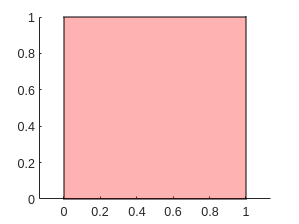

figure()
mesh.plot()

We can even visualize the results in GiD and Paraview if we want

mesh.print('myMesh', 'GiD');
mesh.print('myMesh', 'Paraview');

There's other cool stuff that we can do with Meshes, but we will see that in other tutorials. 

## Mesh generation

There are different ways to generate a new Mesh. If you take a look at the Input folder of Swan, you will see tons of files generated using the GiD software; in other cases, the Meshes are generated using MATLAB's own functions. Let's check these cases.

### Using MATLAB

We can easily generate uniform meshes using MATLAB's `linspace`, `meshgrid` and `mesh2tri `functions, as you can see below

% Generate coordinates
x1 = linspace(-1,1,20);
x2 = linspace(0,1,20);
% Create the grid
[xv,yv] = meshgrid(x1,x2);
% Triangulate the mesh to obtain coordinates and connectivities
[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

Once we have the coordinates and connectivities, we can create a Mesh just like we did in the previous section.

s.coord  = V(:,1:2);
s.connec = F;
mesh = Mesh(s);

Let's check out the Mesh we generated.

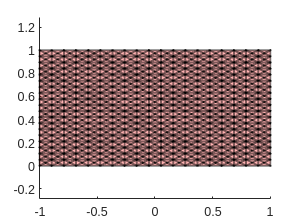

figure()
mesh.plot()

Great, so there we have our first MATLAB-generated mesh.

### Using GiD

*To be added*

Honestly, it's a bit more complicated than creating a Mesh using MATLAB, as we will have to start working on a new software. But hey, fear not, we will do our best:

- Install any GiD version you want from the official website.

- Open up GiD. Go to Data > Problem type > Load, and select the Swan.gid file from this repository.

- Create your desired mesh using GiD. You can check how to do so in their official documentation.

- Once you are ready to export your results to Swan, Calculate > Calculate. This will export a .m file, which you can copy to Swan.

Having followed these steps, you will have a file like those in the Input folder. Reading these files is a bit more complicated than what we did before, but there's a dirty little trick we can do to easily get the Mesh:

file = 'test2d_triangle';
a.fileName = file;
s = FemDataContainer(a);
mesh = s.mesh;

By simply replacing the file with your own file, we can get the Mesh you created. We will learn more about this `FemDataContainer` class in other tutorials.

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!